clear; close; clc;
alpha = deg2rad(linspace(0,90,1000));

%a/b to get the ratio
a = [1,2,3];
b = [1,1,1];

%adjust a and b so that d = 1
d = 2*(a.*b).^(1/2);
a = a./d;
b = b./d;
d = 2*(a.*b).^(1/2);

%other deta
l = 10

l = 10

phi = 0

phi = 0

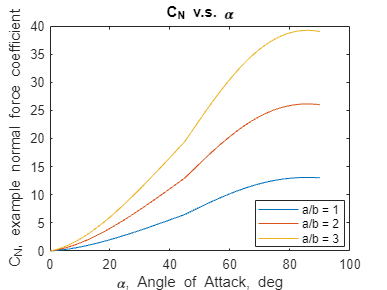


C_N = zeros(length(alpha),3);

for i = 1:length(alpha) 
    C_N(i,:) = normalForceCoeff_liftingBody(l,a,b,phi,alpha(i));
end

figure;
plot(rad2deg(alpha), C_N); title("C_N v.s. \alpha"); xlabel("\alpha, Angle of Attack, deg"); ylabel("C_N, example normal force coefficient"); legend(["a/b = 1", "a/b = 2", "a/b = 3"], "Location","best")